% --- CONFIGURACIÓN DE DATOS Y PARÁMETROS ---
x = [1 2 7 9];
y = [0 0 1 1];

% Parámetros iniciales
w = 1;
b = 0;
w_init = w;
b_init = b;

% Hiperparámetros
nu = 0.1;
epocas = 200;

% --- CONFIGURACIÓN DE ESTILO ---
fuente = 'Times New Roman'; 
filename = 'apprendimento_perceptrone_estilo.gif';

% Pre-asignación de historiales
loss_history = nan(1, epocas);
w_history = nan(1, epocas);
b_history = nan(1, epocas);

% --- INICIALIZACIÓN DE LA FIGURA ---
figure(1);
set(gcf, 'Position', [100, 100, 1100, 500], 'Color', 'w');

% === TÍTULO GLOBAL (Estilo Mixto: Negrita + Normal) ===
txt_titulo = sprintf('\\bfEntrenamiento Perceptrón (Clasificación)\\rm\n w_0 = %.1f | b_0 = %.1f | \\nu = %.2f | Épocas: %d', ...
                     w_init, b_init, nu, epocas);
sgtitle(txt_titulo, 'FontSize', 15, 'FontName', fuente); 

% === SUBPLOT 1: CLASIFICACIÓN (IZQUIERDA) ===
ax1 = subplot(1, 2, 1);
% Ajuste de márgenes
pos1 = get(ax1, 'Position'); pos1(4) = pos1(4) * 0.85; set(ax1, 'Position', pos1);
set(ax1, 'FontName', fuente, 'FontSize', 12);

hold on;
% Dibujamos los datos una sola vez (Clase 0 y Clase 1)
idx0 = (y == 0);
idx1 = (y == 1);
plot(x(idx0), y(idx0), 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 8, 'DisplayName', 'Clase 0');
plot(x(idx1), y(idx1), 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 8, 'DisplayName', 'Clase 1');

% Línea del modelo (Sigmoide) - Inicialización
x_line = linspace(-1, 12, 200);
y_init_curve = 1./(1 + exp(-(w*x_line + b)));
h_model = plot(x_line, y_init_curve, 'k-', 'LineWidth', 2, 'DisplayName', 'Sigmoide');

grid on;
axis([-1 10 -0.1 1.1]); % Límites fijos para ver bien la sigmoide
xlabel('Input (x)', 'FontName', fuente);
ylabel('Probabilidad (y)', 'FontName', fuente);
legend('Location', 'southeast', 'FontName', fuente);
h_title1 = title('Estado Inicial', 'FontName', fuente, 'FontWeight', 'normal');
hold off;

% === SUBPLOT 2: HISTORIAL (DERECHA) ===
ax2 = subplot(1, 2, 2);
% Ajuste de márgenes
pos2 = get(ax2, 'Position'); pos2(4) = pos2(4) * 0.85; set(ax2, 'Position', pos2);
set(ax2, 'FontName', fuente, 'FontSize', 12);

hold on;
% Inicializamos líneas vacías para animar
h_loss = plot(1, 0, 'r-', 'LineWidth', 2, 'DisplayName', 'Loss');
h_w    = plot(1, 0, 'g-', 'LineWidth', 2, 'DisplayName', 'w');
h_b    = plot(1, 0, 'm-', 'LineWidth', 2, 'DisplayName', 'b');

grid on;
xlim([1 epocas]);
% El eje Y lo dejamos dinámico o fijo según preferencia. 
% Aquí un rango amplio inicial:
ylim([-6 4]); 

xlabel('Época', 'FontName', fuente);
h_title2 = title('Dinámica de Entrenamiento', 'FontName', fuente, 'FontWeight', 'normal');
legend('Location', 'northeast', 'FontName', fuente);
hold off;

drawnow;

% --- BUCLE DE ENTRENAMIENTO ---
disp('Iniciando entrenamiento...');

Iniciando entrenamiento...


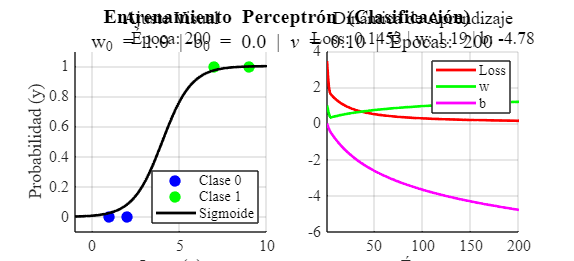

Epoca 20 | Loss: 0.9743
Epoca 40 | Loss: 0.6117
Epoca 60 | Loss: 0.4399
Epoca 80 | Loss: 0.3419
Epoca 100 | Loss: 0.2792
Epoca 120 | Loss: 0.2358
Epoca 140 | Loss: 0.2041
Epoca 160 | Loss: 0.1798
Epoca 180 | Loss: 0.1607
Epoca 200 | Loss: 0.1453



for i = 1:epocas
    % 1. Predicción (Sigmoide)
    z = w.*x + b;
    y_cap = 1./(1 + exp(-z));
    
    % 2. Cálculo de Loss (Entropía cruzada / Log-Loss)
    % Sumamos eps para evitar log(0)
    L = -sum(y.*log(y_cap + eps) + (1 - y).*log(1 - y_cap + eps));
    
    % 3. Guardar Historial
    loss_history(i) = L;
    w_history(i) = w;
    b_history(i) = b;
    
    % --- ACTUALIZACIÓN VISUAL (Solo actualizamos datos, no borramos figura) ---
    
    % Subplot Izquierdo (Curva)
    y_curve_new = 1./(1 + exp(-(w*x_line + b)));
    set(h_model, 'YData', y_curve_new);
    set(h_title1, 'String', sprintf('Ajuste Visual\nÉpoca: %d', i));
    
    % Subplot Derecho (Historial)
    iter = 1:i;
    set(h_loss, 'XData', iter, 'YData', loss_history(1:i));
    set(h_w,    'XData', iter, 'YData', w_history(1:i));
    set(h_b,    'XData', iter, 'YData', b_history(1:i));
    
    set(h_title2, 'String', sprintf('Dinámica de Aprendizaje\nLoss: %.4f | w: %.2f | b: %.2f', L, w, b));
    
    drawnow;
    
    % --- GUARDAR GIF ---
    frame = getframe(gcf); 
    im = frame2im(frame); 
    [imind, cm] = rgb2ind(im, 256); 
    
    % Delay: rápido durante el proceso, pausa al final
    if i == epocas; delay = 2.0; else; delay = 0.05; end
    
    % Escribir cada 2 frames para que el GIF no pese tanto (opcional, aquí guarda todos)
    if i == 1 
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', delay); 
    else 
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', delay); 
    end
    
    % --- ACTUALIZACIÓN DE PARÁMETROS (Gradiente Descendente) ---
    dLw = (y_cap - y) * x';
    dLb = sum(y_cap - y);
    
    w = w - nu * dLw;
    b = b - nu * dLb;
    
    % Debug en consola (opcional, cada 20 épocas)
    if mod(i, 20) == 0
        fprintf('Epoca %d | Loss: %.4f\n', i, L);
    end
end


disp(['GIF guardado correctamente como: ', filename]);

GIF guardado correctamente como: apprendimento_perceptrone_estilo.gif


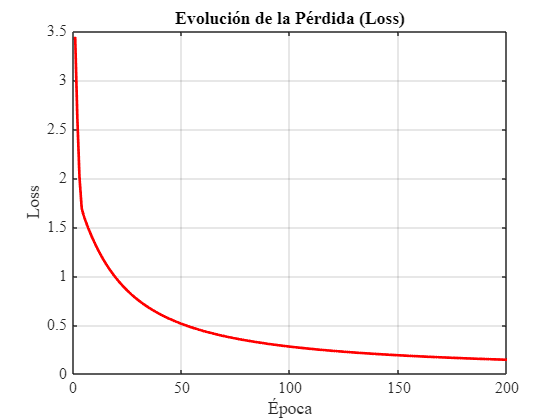


% --- GRÁFICO FINAL ESTÁTICO DE LOSS (Opcional) ---
figure('Name', 'Loss Final', 'Color', 'w');
plot(loss_history, 'r-', 'LineWidth', 2);
title('Evolución de la Pérdida (Loss)', 'FontName', fuente, 'FontWeight', 'bold');
xlabel('Época', 'FontName', fuente);
ylabel('Loss', 'FontName', fuente);
grid on;
set(gca, 'FontName', fuente, 'FontSize', 12);